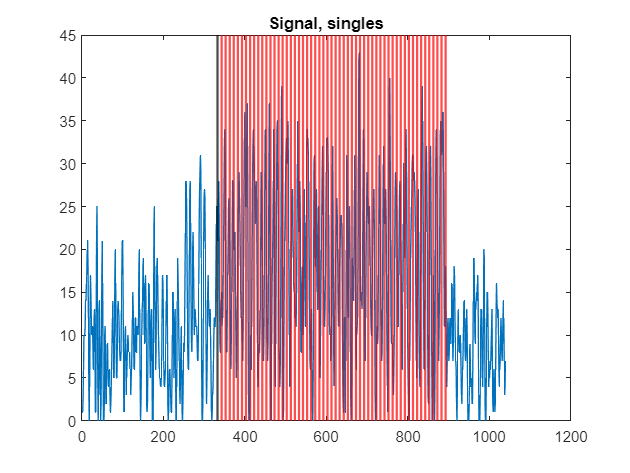

clear
load("tempNeigiamasRodiklisData.mat")

minAmplitude = 0.1;
maxAmplitude = 1.1;
stepCount = 1;

data_binary = [1 0 0 0 1 1 0 1 0 1 0 0 0 0 0 0 0 1 1 0 1 0 1 0 1 0 0 1 1 1 1 0]';
packet_bits = GenerateBits(data_binary);
singleSigLength = 1040;
ADCsignalLong = zeros(1, stepCount*singleSigLength);
idealSignalLong = zeros(1, stepCount*singleSigLength);
for generuojama_amplitude_index = 1:stepCount
    generatedAmplitude = minAmplitude + (maxAmplitude - minAmplitude)/(stepCount-1+1) * (generuojama_amplitude_index-1);
    [idealSignal, noisySignal, discretizedSignal, ADCsignal, ADCpreambule] = GenerateSignal(packet_bits, generatedAmplitude);
    copyIndexStart = singleSigLength*(generuojama_amplitude_index-1)+1;
    copyIndexLast = singleSigLength*(generuojama_amplitude_index);
    ADCsignalLong(copyIndexStart:copyIndexLast) = ADCsignal;
    idealSignalLong(copyIndexStart:copyIndexLast) = idealSignal(1:10:length(idealSignal));
end
%Calculate preambule ending points
[preambule_ends_x, ~] = GenerateTargets(stepCount, convTypes(ConvolutionEnum.extended).expectedMaximum, length(ADCsignal), ADCsignalLong);
%Calculate 2bit ending points
bits_ends_duos = zeros(1, length(packet_bits) / 2);
bits_ends_singles = zeros(1, length(packet_bits));
for i = 1:length(bits_ends_duos)
    bits_ends_duos(i) = i * 20 + preambule_ends_x(1);
end
for i = 1:length(bits_ends_singles)
    bits_ends_singles(i) = i * 10 + preambule_ends_x(1);
end

plot(ADCsignalLong, 'DisplayName', "Signal")
hold on
xline(preambule_ends_x, "black",'LineWidth', 1.5, 'DisplayName', "Preambule end")
xline(bits_ends_singles, "red",'LineWidth', 1.5)
hold off
title("Signal, singles")

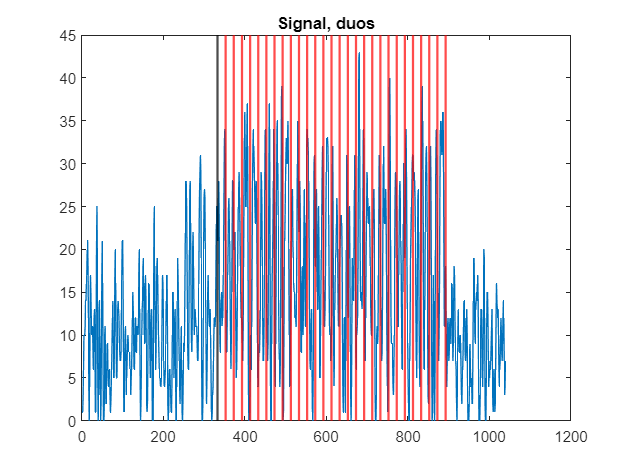


plot(ADCsignalLong, 'DisplayName', "Signal")
hold on
xline(preambule_ends_x, "black",'LineWidth', 1.5, 'DisplayName', "Preambule end")
xline(bits_ends_duos, "red",'LineWidth', 1.5)
hold off
title("Signal, duos")

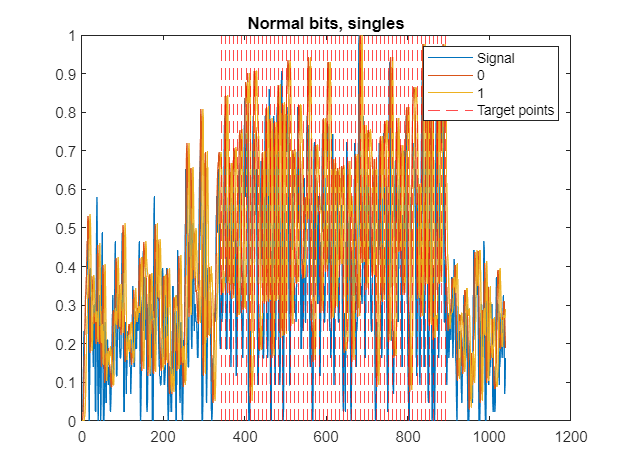

%Create bit masks
bit_1_mask = [1, 1, 1, 1, 1, 0, 0, 0, 0, 0];
bit_0_mask = [0, 0, 0, 0, 0, 1, 1, 1, 1, 1];
bit_masks_singles = [bit_0_mask; bit_1_mask];

bit_00_mask = [bit_0_mask, bit_0_mask];
bit_01_mask = [bit_0_mask, bit_1_mask];
bit_10_mask = [bit_1_mask, bit_0_mask];
bit_11_mask = [bit_1_mask, bit_1_mask];
bit_masks = [bit_00_mask; bit_01_mask; bit_10_mask; bit_11_mask];

bit_1_mask_negative = [1, 1, 1, 1, 1, -1, -1, -1, -1, -1];
bit_0_mask_negative = [-1, -1, -1, -1, -1, 1, 1, 1, 1, 1];
bit_00_mask_negative = [bit_0_mask_negative, bit_0_mask_negative];
bit_01_mask_negative = [bit_0_mask_negative, bit_1_mask_negative];
bit_10_mask_negative = [bit_1_mask_negative, bit_0_mask_negative];
bit_11_mask_negative = [bit_1_mask_negative, bit_1_mask_negative];
bit_masks_negative = [bit_00_mask_negative; bit_01_mask_negative; bit_10_mask_negative; bit_11_mask_negative];

%Correlate signal with individual bit masks
bit_corrs_singles = zeros(2, length(ADCsignalLong));
bit_corrs_duos = zeros(4, length(ADCsignalLong));
bit_corrs_duos_negative = zeros(4, length(ADCsignalLong));
for i = 1:4
    bit_corrs_duos(i, :) = GenerateConv(ADCsignalLong, bit_masks(i, :));
    bit_corrs_duos_negative(i, :) = GenerateConv(ADCsignalLong, bit_masks_negative(i, :));
end
for i = 1:2
    bit_corrs_singles(i, :) = GenerateConv(ADCsignalLong, bit_masks_singles(i, :));
end

plot(normalize(ADCsignalLong, "range"))
hold on
plot(normalize(bit_corrs_singles(1, :), "range"))
plot(normalize(bit_corrs_singles(2, :), "range"))
xline(bits_ends_singles,'--', "color", "red")
hold off
legend("Signal", "0", "1", "Target points")
title("Normal bits, singles")

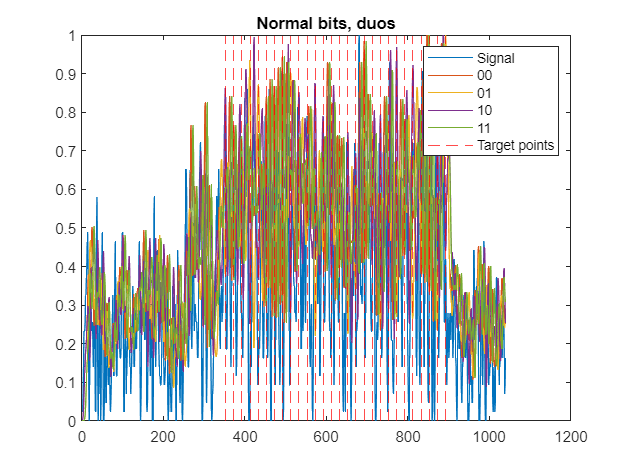


plot(normalize(ADCsignalLong, "range"))
hold on
plot(normalize(bit_corrs_duos(1, :), "range"))
plot(normalize(bit_corrs_duos(2, :), "range"))
plot(normalize(bit_corrs_duos(3, :), "range"))
plot(normalize(bit_corrs_duos(4, :), "range"))
xline(bits_ends_duos,'--', "color", "red")
hold off
legend("Signal", "00", "01", "10", "11", "Target points")
title("Normal bits, duos")

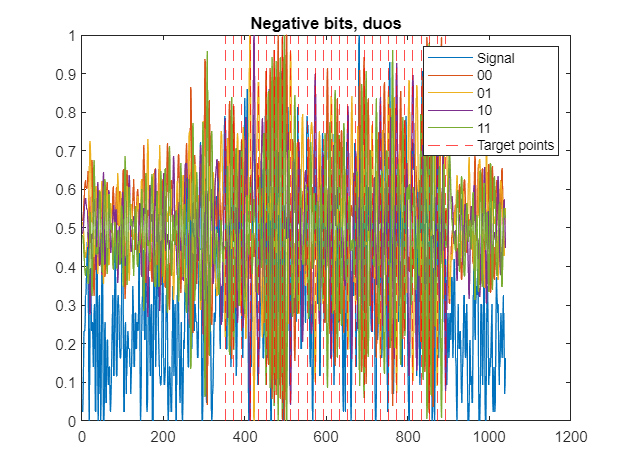

plot(normalize(ADCsignalLong, "range"), 'DisplayName', "Signal")
hold on
plot(normalize(bit_corrs_duos_negative(1, :), "range"))
plot(normalize(bit_corrs_duos_negative(2, :), "range"))
plot(normalize(bit_corrs_duos_negative(3, :), "range"))
plot(normalize(bit_corrs_duos_negative(4, :), "range"))
xline(bits_ends_duos,'--', "color", "red")
hold off
legend("Signal", "00", "01", "10", "11", "Target points")
title("Negative bits, duos")

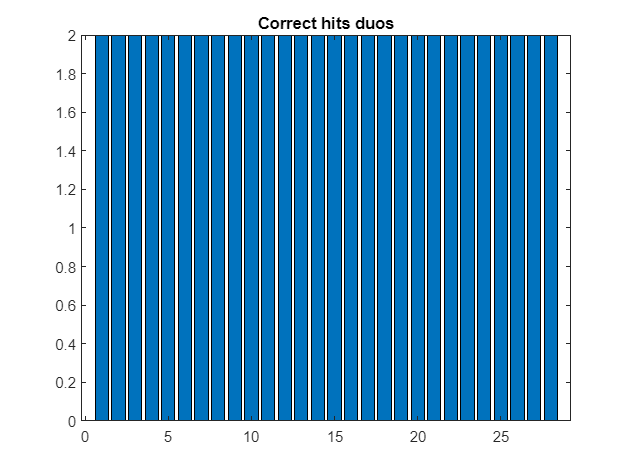

%Calculate correct hits duos
correct_hits_duos = zeros(1, length(bits_ends_duos));
correct_hits_duos_negative = zeros(1, length(bits_ends_duos));
for i = 1:length(bits_ends_duos)
    expected_bits = packet_bits(i*2-1 : i*2);
    %Find correlation with biggest value at target point
    biggest_index = -10000;
    biggest_value = -10000;
    for ii = 1:4
        if bit_corrs_duos(ii, bits_ends_duos(i)) > biggest_value
            biggest_value = bit_corrs_duos(ii, bits_ends_duos(i));
            biggest_index = ii;
        end
    end
    %Check if biggest value is expeted bits
    %TODO: Need to find a better way to do this
    if (biggest_index == 1) && isequal(expected_bits, [0, 0])
        correct_hits_duos(i) = correct_hits_duos(i) + 2;
    elseif (biggest_index == 2) && isequal(expected_bits, [0, 1])
        correct_hits_duos(i) = correct_hits_duos(i) + 2;
    elseif (biggest_index == 3) && isequal(expected_bits, [1, 0])
        correct_hits_duos(i) = correct_hits_duos(i) + 2;
    elseif (biggest_index == 4) && isequal(expected_bits, [1, 1])
        correct_hits_duos(i) = correct_hits_duos(i) + 2;
    end

    %Find correlation with biggest value at target point with negative bits
    biggest_index = -10000;
    biggest_value = -10000;
    for ii = 1:4
        if bit_corrs_duos_negative(ii, bits_ends_duos(i)) > biggest_value
            biggest_value = bit_corrs_duos_negative(ii, bits_ends_duos(i));
            biggest_index = ii;
        end
    end
    %Check if biggest value is expeted bits
    %TODO: Need to find a better way to do this
    if (biggest_index == 1) && isequal(expected_bits, [0, 0])
        correct_hits_duos_negative(i) = correct_hits_duos_negative(i) + 2;
    elseif (biggest_index == 2) && isequal(expected_bits, [0, 1])
        correct_hits_duos_negative(i) = correct_hits_duos_negative(i) + 2;
    elseif (biggest_index == 3) && isequal(expected_bits, [1, 0])
        correct_hits_duos_negative(i) = correct_hits_duos_negative(i) + 2;
    elseif (biggest_index == 4) && isequal(expected_bits, [1, 1])
        correct_hits_duos_negative(i) = correct_hits_duos_negative(i) + 2;
    end
end

bar(correct_hits_duos)
title("Correct hits duos")

sum(correct_hits_duos)

ans = 56

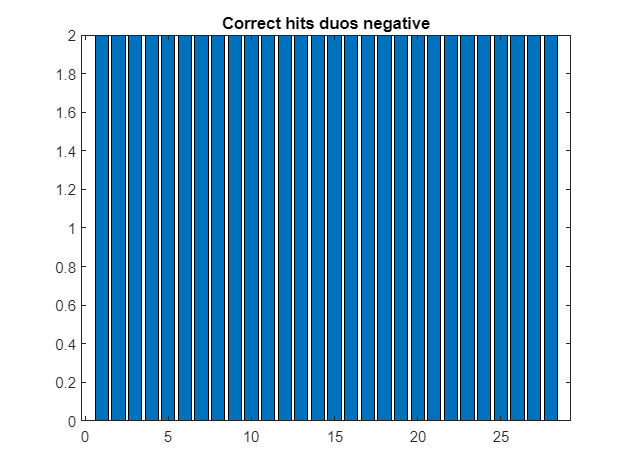

bar(correct_hits_duos_negative)
title("Correct hits duos negative")

sum(correct_hits_duos_negative)

ans = 56

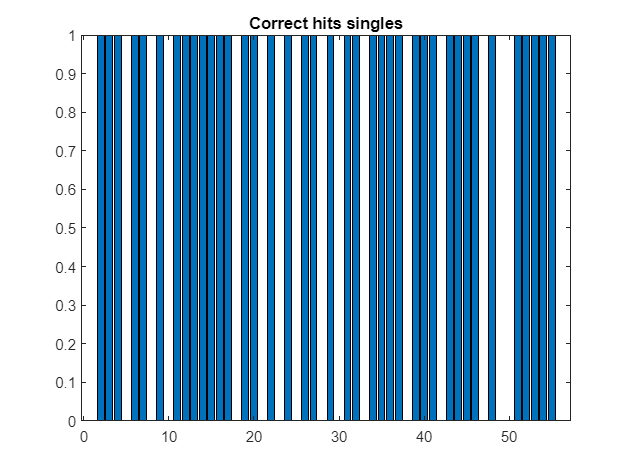

%Calculate correct hits singles
correct_hits_singles = zeros(1, length(bits_ends_singles));

for i = 1:length(bits_ends_singles)
    expected_bits = packet_bits(i);
    %Find correlation with biggest value at target point
    biggest_index = -10000;
    biggest_value = -10000;
    for ii = 1:2
        if bit_corrs_singles(ii, bits_ends_singles(i)) > biggest_value
            biggest_value = bit_corrs_duos(ii, bits_ends_singles(i));
            biggest_index = ii;
        end
    end
    %Check if biggest value is expeted bits
    %TODO: Need to find a better way to do this
    if (biggest_index == 1) && (expected_bits == 0)
        correct_hits_singles(i) = correct_hits_singles(i) + 1;
    elseif (biggest_index == 2) && (expected_bits == 1)
        correct_hits_singles(i) = correct_hits_singles(i) + 1;
    end
end
bar(correct_hits_singles)
title("Correct hits singles")

sum(correct_hits_singles)

ans = 39